**CLASSICAL CONTROL DESIGN**

clear
% Load available channels
load channels.mat

**PITCH ATTITUDE CONTROL**

We need pitch angle $\theta \;$regulated by control of elevator angle $\delta_e$. TF: $G_{\theta \delta_e }$:

[G1] = channelTF(Xlong_s(4,1))

G1 =
 
                -5.115e33 s^2 - 1.037e34 s - 3.733e32
  ------------------------------------------------------------------
  1.462e32 s^4 + 1.316e33 s^3 + 4.134e33 s^2 + 1.901e32 s + 1.205e32
 
Continuous-time transfer function.



pole(G1)

ans =   -4.4827 + 2.7985i
  -4.4827 - 2.7985i
  -0.0186 + 0.1708i
  -0.0186 - 0.1708i


zero(G1)

ans =    -1.9907
   -0.0367


Open Loop behavior:

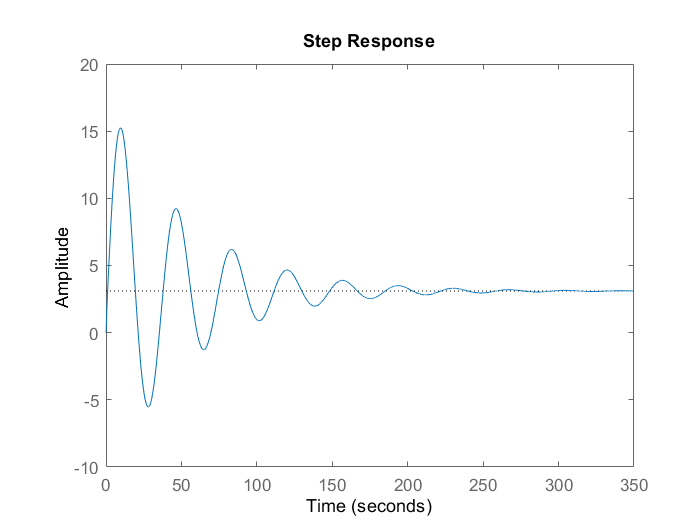

step(-G1)

Actuator dynamics for $\delta_e$:


$$\delta_e =\frac{1}{T_e s+1}u_e$$


% Actuator Dynamics TF
T_e = 0.1; % Value from assignments
Ac_tf = tf([1],[T_e,1]);
% Consider actuator dynamic 
G1 = Ac_tf*G1;

Use PID controller for closed-loop response. Use MATLAB's PID Tuner for gain values:

Kp = -2.617;
Ki = -2.804;
Kd = -0.6106;
syms s
C_PID = Kp + Ki/s + Kd*s;
[num,den] = numden(C_PID);
TFnum = sym2poly(num);
TFden = sym2poly(den); 
C_PID = tf(TFnum,TFden)

C_PID =
 
  -3053 s^2 - 13085 s - 14020
  ---------------------------
            5000 s
 
Continuous-time transfer function.



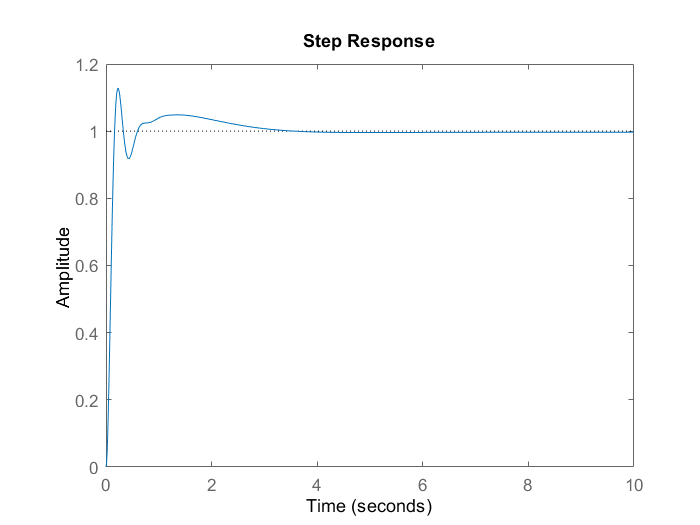

sys_cl = feedback(C_PID*G1,1);
t = 0:0.01:10;
step(sys_cl,t)

**PITCH RATE CONTROL **

We need pitch rate $q$ regulated by control of elevator angle $\delta_e$. TF: $G_{q\delta_e }$:

[G2] = channelTF(Xlong_s(3,1))

G2 =
 
              -5.115e33 s^3 - 1.037e34 s^2 - 3.733e32 s
  ------------------------------------------------------------------
  1.462e32 s^4 + 1.316e33 s^3 + 4.134e33 s^2 + 1.901e32 s + 1.205e32
 
Continuous-time transfer function.



pole(G2)

ans =   -4.4827 + 2.7985i
  -4.4827 - 2.7985i
  -0.0186 + 0.1708i
  -0.0186 - 0.1708i


zero(G2)

ans =          0
   -1.9907
   -0.0367


Open Loop behavior:

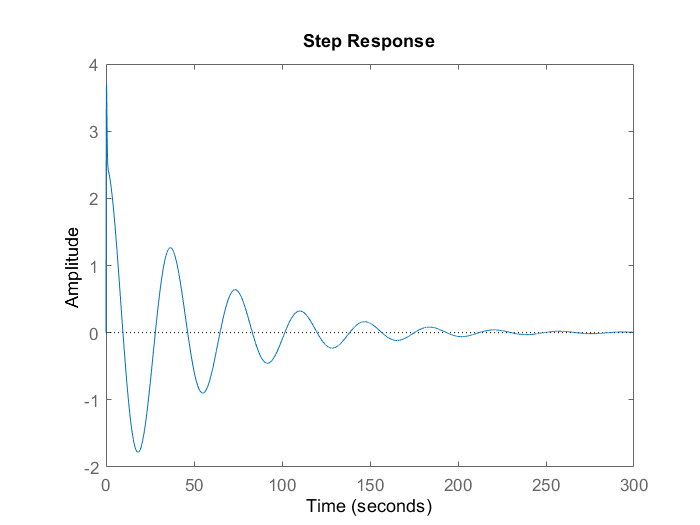

step(-G2)

Actuator dynamics for $\delta_e$:


$$\delta_e =\frac{1}{T_e s+1}u_e$$


% Actuator Dynamics TF
T_e = 0.1; % Value from assignments
Ac_tf = tf([1],[T_e,1]);
% Consider actuator dynamic 
G2 = Ac_tf*G2;

Use PID controller for closed-loop response. Use MATLAB's PID Tuner for gain values:

Kp = -1.216;
Ki = -9.199;
Kd = -0.0402;
syms s
C_PID = Kp + Ki/s + Kd*s;
[num,den] = numden(C_PID);
TFnum = sym2poly(num);
TFden = sym2poly(den); 
C_PID = tf(TFnum,TFden)

C_PID =
 
  -201 s^2 - 6080 s - 45995
  -------------------------
           5000 s
 
Continuous-time transfer function.



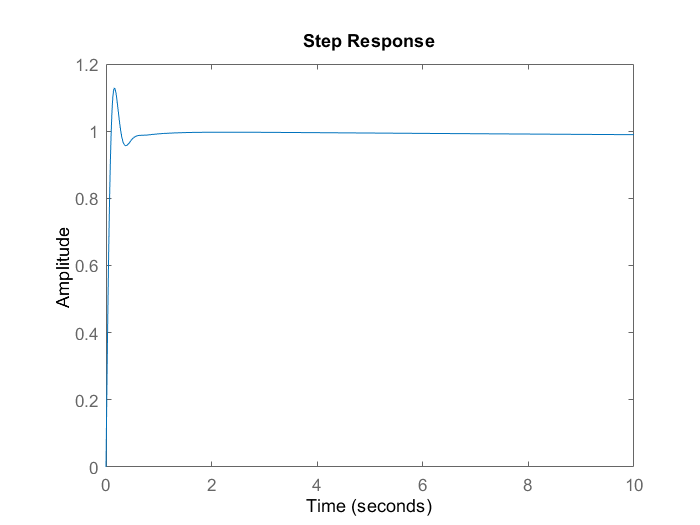

sys_cl = feedback(C_PID*G2,1);
step(sys_cl,t)

**SPEED CONTROL TROUGH **$\delta_p$

We need velocity $u$ regulated by control of throttle $\delta_p$. TF: $G_{u\delta_p }$:

[G3] = channelTF(Xlong_s(1,2))

G3 =
 
                2.581e32 s^3 + 2.312e33 s^2 + 7.2e33 s
  ------------------------------------------------------------------
  1.462e32 s^4 + 1.316e33 s^3 + 4.134e33 s^2 + 1.901e32 s + 1.205e32
 
Continuous-time transfer function.



pole(G3)

ans =   -4.4827 + 2.7985i
  -4.4827 - 2.7985i
  -0.0186 + 0.1708i
  -0.0186 - 0.1708i


zero(G3)

ans =    0.0000 + 0.0000i
  -4.4786 + 2.8002i
  -4.4786 - 2.8002i


Open Loop behavior:

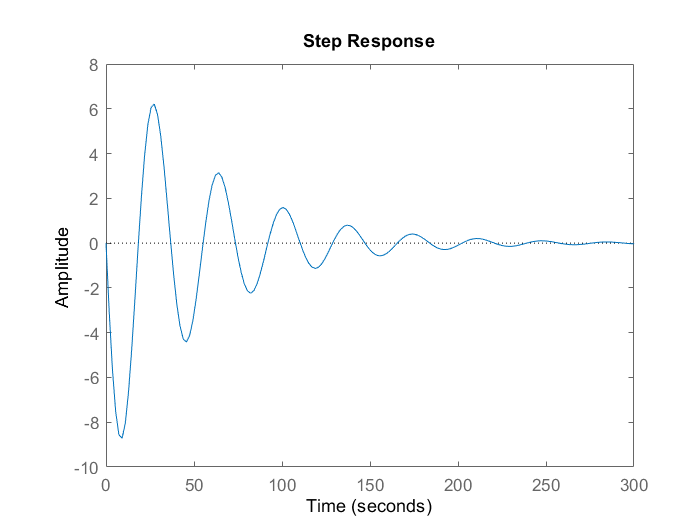

step(-G3)

Actuator dynamics for $\delta_p$:


$$\delta_p =\frac{1}{T_p s+1}u_p$$


% Actuator Dynamics TF
T_p = 3.5; % Value from assignments
Ac_tf = tf([1],[T_p,1]);
% Consider actuator dynamic 
G3 = Ac_tf*G3;

Use PID controller for closed-loop response. Use MATLAB's PID Tuner for gain values:

Kp = 41.28;
Ki = 26.4;
Kd = 16.13;
syms s
C_PID = Kp + Ki/s + Kd*s;
[num,den] = numden(C_PID);
TFnum = sym2poly(num);
TFden = sym2poly(den); 
C_PID = tf(TFnum,TFden)

C_PID =
 
  1613 s^2 + 4128 s + 2640
  ------------------------
           100 s
 
Continuous-time transfer function.



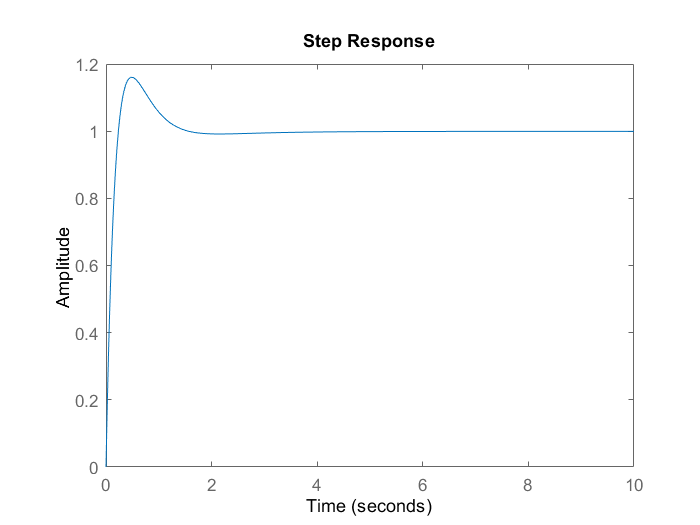

sys_cl = feedback(C_PID*G3,1);
t = 0:0.01:10;
step(sys_cl,t)

**SPEED CONTROL TROUGH **$\delta_e$

We need velocity $u$ regulated by control of throttle $\delta_e$. TF: $G_{u\delta_e }$:

[G4] = channelTF(Xlong_s(1,1))

G4 =
 
                 1.125e32 s^2 + 6.995e34 s + 9.945e34
  ------------------------------------------------------------------
  1.462e32 s^4 + 1.316e33 s^3 + 4.134e33 s^2 + 1.901e32 s + 1.205e32
 
Continuous-time transfer function.



pole(G4)

ans =   -4.4827 + 2.7985i
  -4.4827 - 2.7985i
  -0.0186 + 0.1708i
  -0.0186 - 0.1708i


zero(G4)

ans =  -620.3691
   -1.4250


Open Loop behavior:

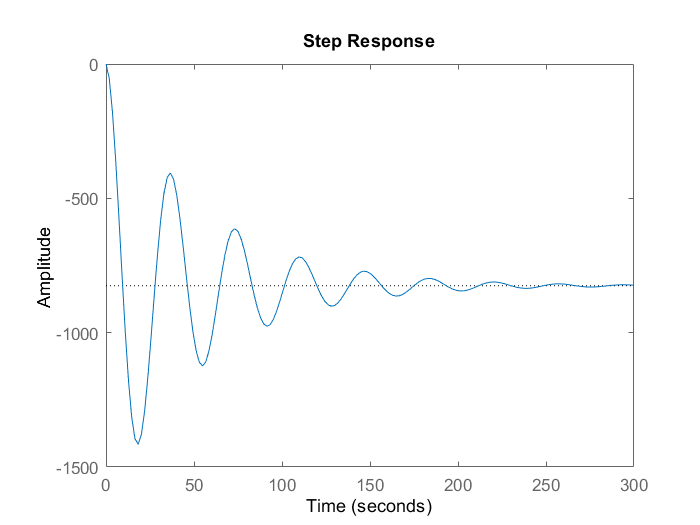

step(-G4)

Actuator dynamics for $\delta_e$:


$$\delta_e =\frac{1}{T_e s+1}u_e$$


% Actuator Dynamics TF
T_e = 0.1; % Value from assignments
Ac_tf = tf([1],[T_e,1]);
% Consider actuator dynamic 
G4 = Ac_tf*G4;

Use PID controller for closed-loop response. Use MATLAB's PID Tuner for gain values:

Kp = 0.001069;
Ki = 3.42e-5;
Kd = 0.00739;
syms s
C_PID = Kp + Ki/s + Kd*s;
[num,den] = numden(C_PID);
TFnum = sym2poly(num);
TFden = sym2poly(den); 
C_PID = tf(TFnum,TFden)

C_PID =
 
  3.408e21 s^2 + 4.93e20 s + 1.577e19
  -----------------------------------
              4.612e23 s
 
Continuous-time transfer function.



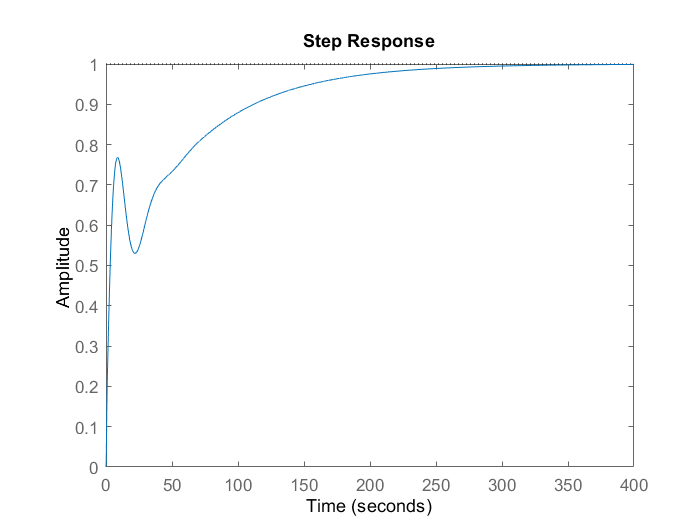

sys_cl = feedback(C_PID*G4,1);
t = 0:0.01:400;
step(sys_cl,t)

**ROLL CONTROL**

We need roll angle $\phi$ regulated by control of aileron $\delta_a$. TF: $G_{\phi \delta_a }$:

[G5] = channelTF(Xlatr_s(4,1))

G5 =
 
                -2.758e34 s^2 - 4.151e34 s - 2.996e35
  ------------------------------------------------------------------
  3.654e32 s^4 + 5.299e33 s^3 + 1.045e34 s^2 + 5.098e34 s + 9.114e32
 
Continuous-time transfer function.



pole(G5)

ans =  -13.1326 + 0.0000i
  -0.6757 + 3.1827i
  -0.6757 - 3.1827i
  -0.0179 + 0.0000i


zero(G5)

ans =   -0.7527 + 3.2087i
  -0.7527 - 3.2087i


Open Loop behavior:

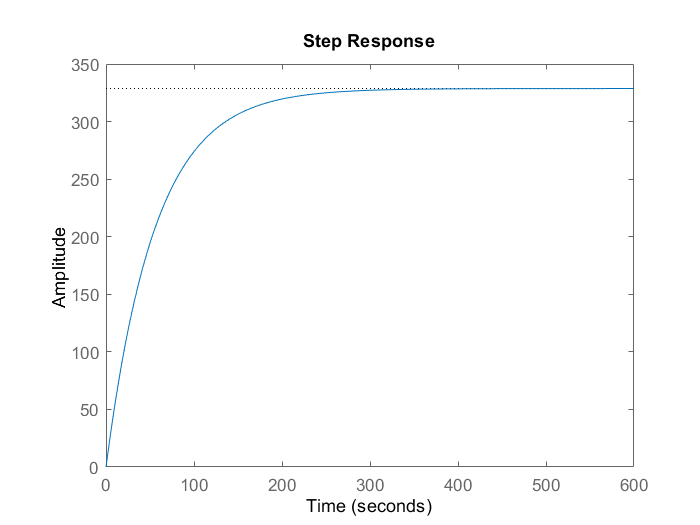

step(-G5)

Actuator dynamics for $\delta_a$:


$$\delta_a =\frac{1}{T_a s+1}u_a$$


% Actuator Dynamics TF
T_a = 0.0495; % Value from Stevens Book page 442
Ac_tf = tf([1],[T_a,1])

Ac_tf =
 
       1
  ------------
  0.0495 s + 1
 
Continuous-time transfer function.



% Consider actuator dynamic 
G5 = Ac_tf*G5;

Use PID controller for closed-loop response. Use MATLAB's PID Tuner for gain values:

Kp = -0.05409;
Ki = -0.001815;
Kd = -0.01454;
syms s
C_PID = Kp + Ki/s + Kd*s;
[num,den] = numden(C_PID);
TFnum = sym2poly(num);
TFden = sym2poly(den); 
C_PID = tf(TFnum,TFden)

C_PID =
 
  -2.095e20 s^2 - 7.795e20 s - 2.616e19
  -------------------------------------
               1.441e22 s
 
Continuous-time transfer function.



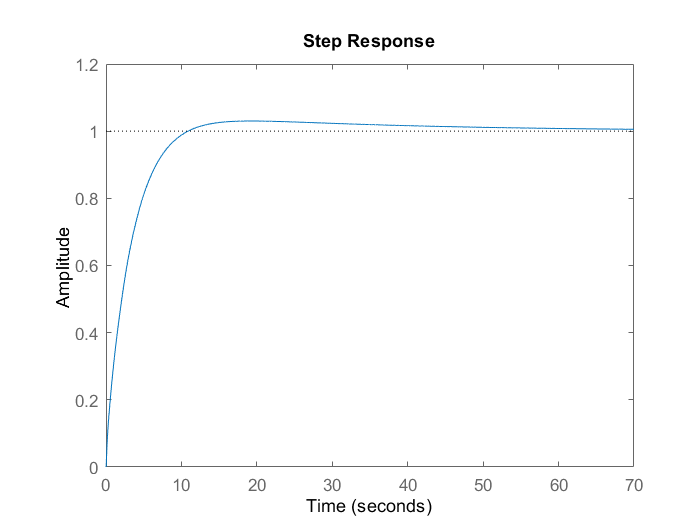

sys_cl = feedback(C_PID*G5,1);
t = 0:0.01:70;
step(sys_cl,t)

**YAW DAMPER**

We need yawing rate $r$ regulated by control of rudder $\delta_r$. TF: $G_{r\delta_r }$:

[G6] = channelTF(Xlatr_s(3,2))

G6 =
 
         -3.743e33 s^3 - 5.005e34 s^2 - 4.636e33 s - 1.426e34
  ------------------------------------------------------------------
  3.654e32 s^4 + 5.299e33 s^3 + 1.045e34 s^2 + 5.098e34 s + 9.114e32
 
Continuous-time transfer function.



pole(G6)

ans =  -13.1326 + 0.0000i
  -0.6757 + 3.1827i
  -0.6757 - 3.1827i
  -0.0179 + 0.0000i


zero(G6)

ans =  -13.2998 + 0.0000i
  -0.0358 + 0.5339i
  -0.0358 - 0.5339i


Open Loop behavior:

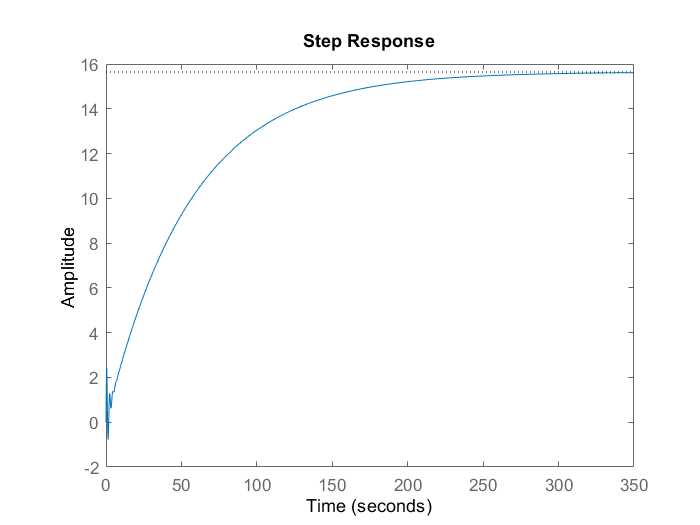

step(-G6)

Actuator dynamics for $\delta_r$:


$$\delta_r =\frac{1}{T_r s+1}u_r$$


% Actuator Dynamics TF
T_r = 0.0495; % Value from Stevens Book page 442
Ac_tf = tf([1],[T_r,1])

Ac_tf =
 
       1
  ------------
  0.0495 s + 1
 
Continuous-time transfer function.



% Consider actuator dynamic 
G6 = Ac_tf*G6;

Use PID controller for closed-loop response. Use MATLAB's PID Tuner for gain values:

Kp = -0.02691;
Ki = -0.001213;
Kd = 0;
syms s
C_PID = Kp + Ki/s + Kd*s;
[num,den] = numden(C_PID);
TFnum = sym2poly(num);
TFden = sym2poly(den); 
C_PID = tf(TFnum,TFden)

C_PID =
 
  -1.939e20 s - 8.741e18
  ----------------------
        7.206e21 s
 
Continuous-time transfer function.



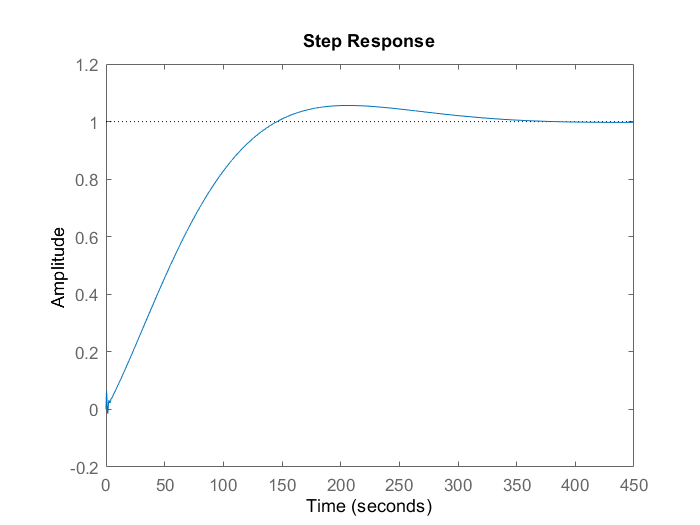

sys_cl = feedback(C_PID*G6,1);
t = 0:0.01:450;
step(sys_cl,t)

General observation of controlled channels:

- Stable response of Open-loop systems.

- Good response to PID controller in feedback loop.

- Correct tracking of unit step command.